clear;
close all;
clc;

1) Load data

path='data\SRAS\Task 3\Task_3_CpTi_small.mat';
load(path);

2) Maximum points in rawdata

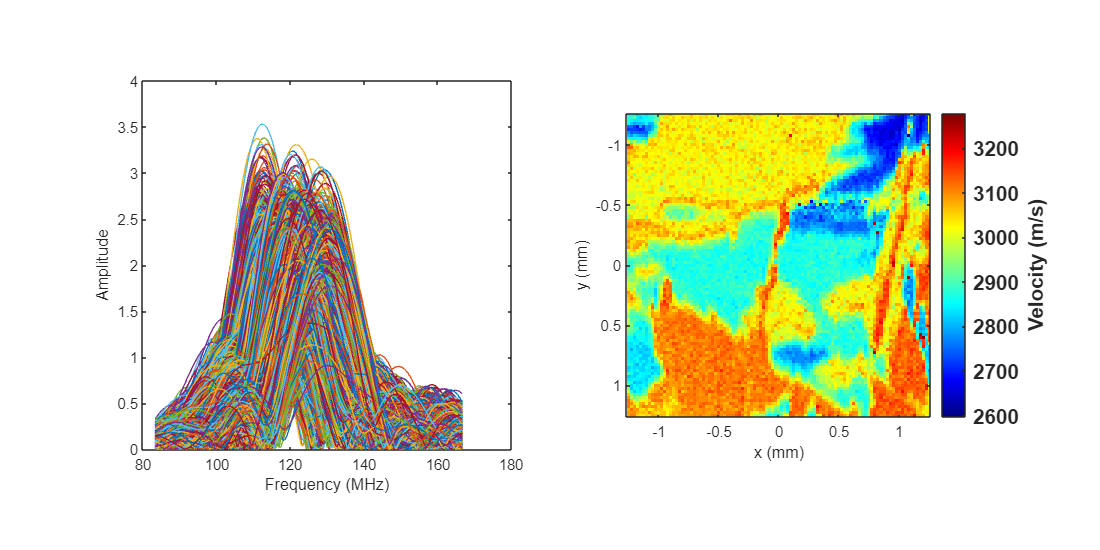

tic
rawdata_envolope=abs(rawdata);
[frequency_max,idx]=max(rawdata_envolope,[],3); %find the max frequency resoponse of each point,and get is index

for n=1:length(y)
    for m=1:length(x)
        frequency_max(n,m)=fscale(idx(n,m));    %find the value of frequency with max frequency index of each point
    end
end

lambda = 24e-6;

velocity = frequency_max*lambda;                %calculate velocity of each point
velocityMax=max(velocity,[],'all');
velocityMin=min(velocity,[],'all');

% Create the figure
figure;

% Set size for the overall figure window
set(gcf, 'Position', [100, 100, 1000, 500]); % 10x5 total size (2 subplots of 5x5 each)

% First subplot (5x5) - Plotting rawdata frequency
subplot(1,2,1)
for n = 1:101
    for m = 1:101
        plot(fscale*1e-6, squeeze(rawdata_envolope(n,m,:)));hold on
    end
end
xlabel('Frequency (MHz)')
ylabel('Amplitude')
axis square; % Make the plot square (5x5)

% Second subplot (5x5) - Displaying velocity map
subplot(1,2,2)
imagesc(x, y, velocity)
axis equal;
axis tight;
xlabel('x (mm)')
ylabel('y (mm)')
clim([velocityMin, velocityMax])

% Add colorbar and format
cb = colorbar;
ylabel(cb, 'Velocity (m/s)', 'FontSize', 14, 'FontWeight', 'bold'); % Set label font size and make it bold

% Set colorbar tick labels to bold and size 14
set(cb, 'FontSize', 14, 'FontWeight', 'bold');

colormap(jet)

toc

Elapsed time is 12.064245 seconds.


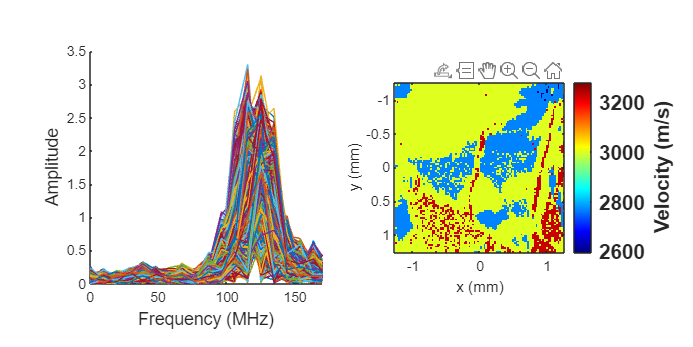

%use tmptrc to map velocity
tic
pts = length(xscale);
fs = 1/(xscale(2)-xscale(1)); 
frequencies = zeros(size(tmptrc,1),size(tmptrc,2));                 % define  zeros to store frequencies
spectrum = zeros(size(tmptrc,1),size(tmptrc,2),size(tmptrc,3)/2);   % vice versa for frequency domain spectrums
freq = fs*(0:(pts/2-1))/pts;

for n=1:length(x)
    for m=1:length(y)
        signal=squeeze(tmptrc(n,m,:));% squeeze the time domain signal of one point
        localSpectrum=abs(fft(signal,pts));
        spectrum(n,m,:)=localSpectrum((1:pts/2));
        [frequencyMax,idx] = max(spectrum(n,m,:));
        frequencies(n,m) = freq(idx); % maximum frequencies
    end
end

% Create the figure
figure;

% Set size for the overall figure window
set(gcf, 'Position', [100, 100, 1000, 500]); % Adjust figure size (10x5 for two 5x5 subplots)

% First subplot: Plot frequency spectrum for one pixel
subplot(1,2,1)
hold on;
for n = 1:101
    for m = 1:101
        plot(freq*1e-6, squeeze(abs(spectrum(n,m,:))));
    end
end
xlabel('Frequency (MHz)', 'FontSize', 12)
ylabel('Amplitude', 'FontSize', 12)
xlim([0, 170])
axis square; % Make the plot square

% Calculate velocity from frequencies
velocitySAW = frequencies * lambda; % Calculate velocity
surfaceMaxVel = max(velocitySAW, [], 'all'); % Max velocity
surfaceMinVel = min(velocitySAW, [], 'all'); % Min velocity

% Second subplot: Plot velocity map
subplot(1,2,2)
imagesc(x, y, velocitySAW)
axis equal;
axis tight;
xlabel('x (mm)')
ylabel('y (mm)')
clim([velocityMin, velocityMax])

% Add colorbar and format
cb = colorbar;
ylabel(cb, 'Velocity (m/s)', 'FontSize', 14, 'FontWeight', 'bold'); % Set label font size and make it bold

% Set colorbar tick labels to bold and size 14
set(cb, 'FontSize', 14, 'FontWeight', 'bold');

% Apply colormap
colormap(jet)




toc

Elapsed time is 7.818858 seconds.
